% NEED TO LOAD X from SET_seg data and S = X

Fs     = 250;
fVec   = 12:2:30; 
ncycs  = [2 3 7 14];
n_freq = length(fVec); n_tst = length(ncycs);

Sf     = bandpass(S,[13 30],Fs);
Sfm    = mean(Sf,2) * 10 + fVec(n_freq/2);
n_samp = length(Sfm);
time   = linspace(0,n_samp*1000/Fs,n_samp);
freqs  = 1:n_freq;

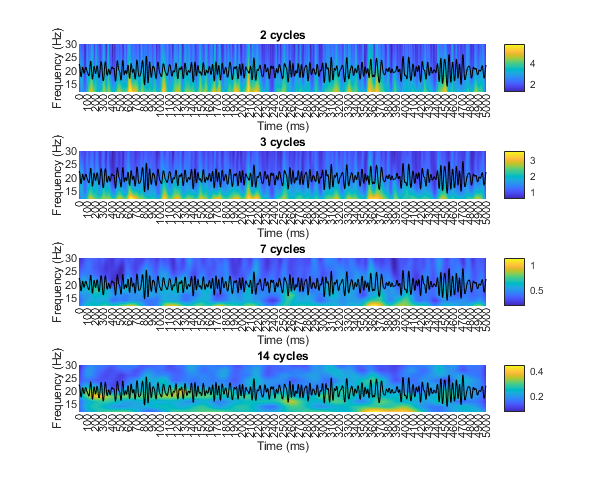

figure('Position',[25 250 2000 400*n_tst]), hold on
for i = 1:n_tst
    tfr(i).tfr = spectralevents_ts2tfr(S,fVec,Fs,ncycs(i));
    tfr(i).min = min(min(tfr(i).tfr)); tfr(i).max = max(max(tfr(i).tfr));

    ax(i) = subplot(n_tst,1,i); hold on
    pcolor(time,fVec,tfr(i).tfr), shading interp; colorbar
    plot(time,Sfm,'color','#000'), xlabel('Time (ms)'), ylabel('Frequency (Hz)')
    title([int2str(ncycs(i)) ' cycles'])
    xticks(0:100:time(end)), ylim([fVec(1) fVec(end)])
end
linkaxes(ax)


% clims = [min([tfr.min]) max([tfr.max])];
% for i=1:n_tst
%     caxis(ax(i),clims)
% end


tVec = (1:size(S,2))/Fs;
for i_f = 1:n_freq
    wav(i_f,:) = morlet(fVec(i_f),tVec,7);
end

function y = morlet(f,t,width)
% Morlet's wavelet for frequency f and time t. 
% The wavelet will be normalized so the total energy is 1.
% width defines the ``width'' of the wavelet. 
% A value >= 5 is suggested.
%
% Ref: Tallon-Baudry et al., J. Neurosci. 15, 722-734 (1997)

sf = f/width;
st = 1/(2*pi*sf);
A = 1/(st*sqrt(2*pi));
y = A*exp(-t.^2/(2*st^2)).*exp(1i*2*pi*f.*t);
end